# Zernike polynomial calculations

Zernike polynomials represent the wavefront aberration over the pupil.  The aberration represents the difference in the wavefront phase from the ideal wavefront.  Hence, we can plot the 'phase' of the wavefront aberration in the pupil.  This is called the 'pupil function'.

The parameters we use to control the wavefront aberrations are described in t_wvfOverview.  This tutorial illustrates the effect of changing different polynomial coefficients of theses aberrations, particularly with respect to their impact on the PSF. 

### Notation

The polynomials can be expressed (referenced) using several formats.  

The polynomials can also be represented in a single-indexing scheme (j) using OSA standards, which is easier to manage in vector form for Matlab. We use that method here.  There are ISETCam functions to translate between labeling methods (wvfOSAIndexToName, wvfOSAToVectorIndex,wvfOSAToZernikeNM).

Another approach is to use two indices, 

- one representing the highest order of the radial polynomial term (n), and 

- the other representing the frequency of the azimuthal sinusoid (m). 

Each radial order has (order+1) number of polynomial terms (and therefore, order+1 number of Zernike coefficients to represent them). Thus, 0th order has 1 term, 1st order has 2 terms, etc.

### See also:

  t_wvfOverview.mlx

## Initialize plotting parameters

ieInit;

The tutorial only uses 1 wavelength, although the code typically specifies multiple wavelengths. For plotting in this tutorial, we use these parameters. 

waveIdx = 1;
maxMM = 2;       % For plotting
maxUM = 20;      % For plotting.
pupilfuncrangeMM = 5;  % For plotting

## Diffraction limited PSF

The diffraction limited wavefront  has the 0's for all Zernike coeffs. Notice that the calcpupilMM is by default 3, meaning we are simulating the wavefront PSF for a pupil of 3MM diameter.  This code prints the structure parameters to help you get a sense of what is in it.

wvf0 = wvfCreate;
wvfPrint(wvf0);


Wavefront structure name is default

Measurement conditions
	Pupil size (mm): 8
	Wavelenth (nm): 550
	Optical axis (deg): 0
	Observer accommodation (diopters): 0
	Observer focus correction (diopters): 0
Spatial sampling conditions
	Sampling constant across wavelength in psf domain
	Number of spatial samples (pixels) for pupil function/psf: 201
	Size of sampled pupil plane (mm) at measurement wavelength: 16.212
	Pupil plane sampling interval (mm/pixel) at measurement wavelength: 0.0806567
	PSF sampling interval (arcmin/pixel) at measurement wavelength: 0.116627
Calculation parameters
	Pupil size (mm): 3
	Optical axis (deg): 0
	Observer accommodation (diopters): 0
	Wavelengths:  550


We have a second way of describing the wavefront that can also be helpful.  This method describes sampling properties and the extent of the support in the spatial and frequency domains. It includes units.

wvfSummarize(wvf0);


wavefront struct name: default
-------------------
f number	 5.729433
f length	 17.188300	 mm
um per deg	 300.000043	 um
calc pupil diam	 3.000000	 mm

Reference
------
n samples	 201
ref pupil plane	 16.212000	 mm
ref pupil dx	 80.656716	 um

Measured
------
zCoeffs:	 0.00 
zDiameter:	 8.000000	 mm
Max OTF freq	 857.432538	 cyc/mm
OTF df		 8.574325	 cyc/mm
Max PSF support	 58.313626	 um
PSF dx		 0.583136	 um
-------------------


## Airy Disk

The plot shows an Airy disk computed from the Zernike polynomials; that is representing the diffraction-limited PSF obtained when the Zernike coefficients are all zero. The plot includes the first zero crossing, which defines the  'Airy Disk'.

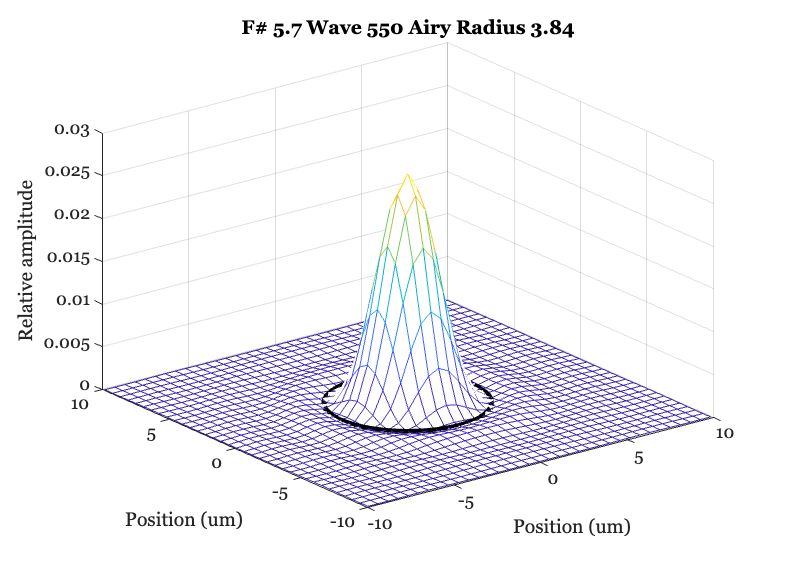

wvf0 = wvfCompute(wvf0);
wList = 550;
wvfPlot(wvf0,'psf','unit','um','wave',wList,'plot range', maxUM/2,'airy disk',true);

## Examine how the first non-zero Zernike coefficient contributes to the PSF.

For the low order polynomial coefficients, wvfSet understands the coefficient names.  Type into the Matlab command window 

for a list of available names.  Here is a link to an [astronomy site](https://www.telescope-optics.net/monochromatic_eye_aberrations.htm) with the names. 

oblique_astig = 2;   % The value                          
wvf3 = wvfSet(wvf0,'zcoeffs',oblique_astig,{'oblique_astigmatism'});

We use wvfComputePupilFunction separately here. This function is called by wvfCompute, which we will use from now on. We can see that the phase changes seem to be aligned with the + and - 45 degree axes, which makes sense for oblique astigmatism.

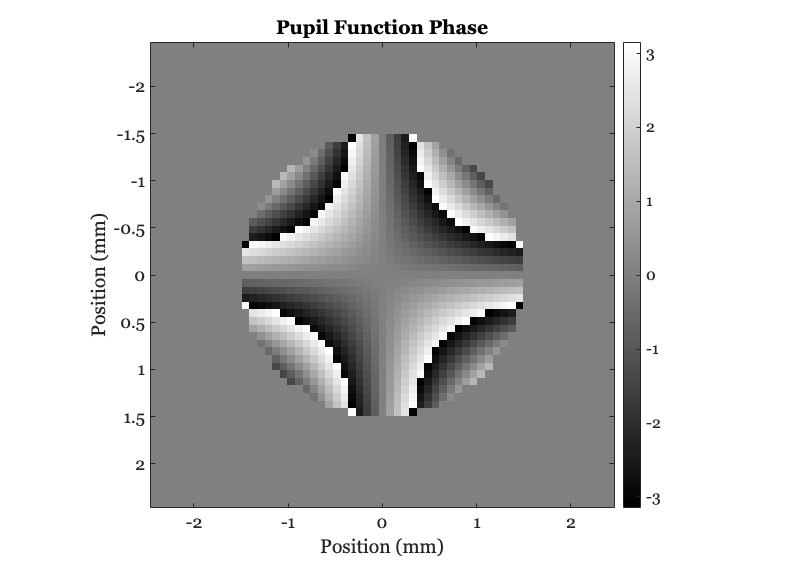

wvf3 = wvfComputePupilFunction(wvf3);
wvfPlot(wvf3,'2d pupil phase space','unit','mm','wave',wList,'plot range',pupilfuncrangeMM/2);

## Plot the PSF

While the pupil functions are specified by Zernike polynomials, it can be hard to understand their meaning. We'd much prefer to look at the PSF, which gives us an idea of how the pupil will blur an image. This is essentially done by applying a Fourier Transform to the pupil function, which is implemented when we call wvfCompute.

wvf3 = wvfCompute(wvf3); 

We can plot the normalized PSF for a pupil only whose only aberration is the 45 degree astigmatism. As you can see, this no longer looks like the narrow, diffraction-limited PSF. It has also lost its radial symmetry. The higher the order of Zernike polynomial, the more complex the associated PSF will be.

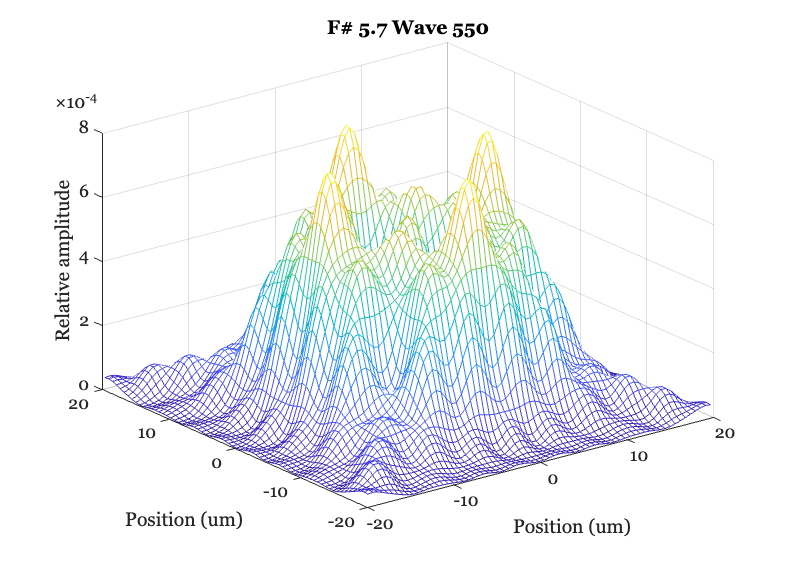

wvfPlot(wvf3, 'psf','unit','um','plot range',maxUM);

## Astigmatism

Astigmatism describes a difference in focus between different orientations.  It can be specified along the 0 or 90 degree axis (vertical or horizontal). Unlike the 3rd coefficient, this coefficient for astigmatism is aligned to the x and y axes.

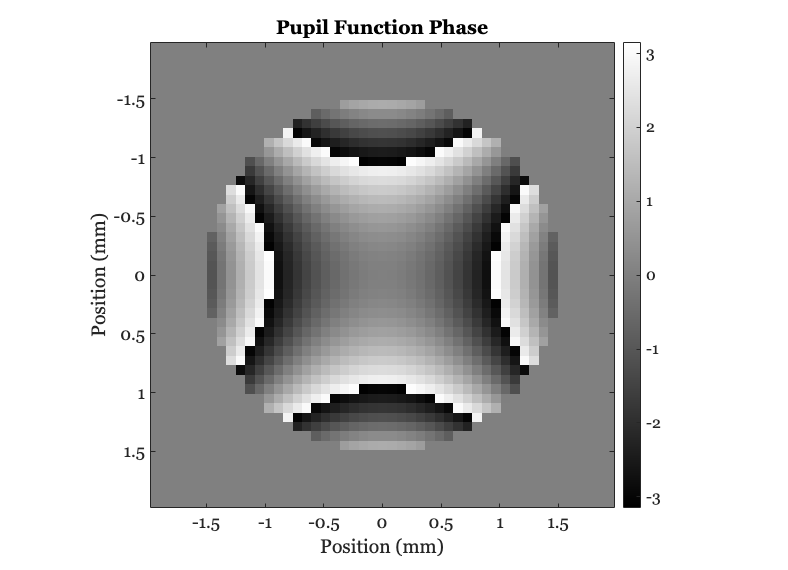

vertical_astig = 2;                         
wvf5 = wvfSet(wvf0,'zcoeffs',vertical_astig,{'vertical_astigmatism'});
wvf5 = wvfCompute(wvf5);
wvfPlot(wvf5,'2d pupil phase space','unit','mm','wave',wList,'plot range',maxMM);

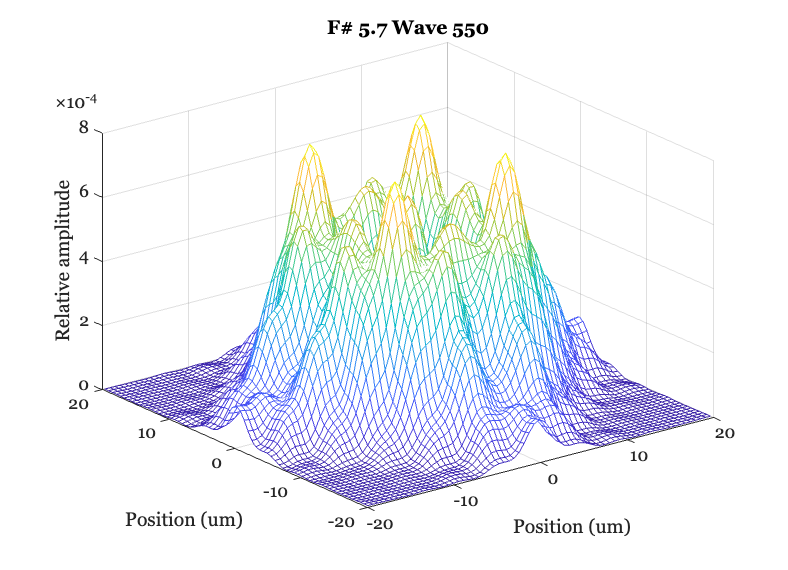

wvfPlot(wvf5,'psf','unit','um','wave',wList,'plot range',maxUM);

## Pupil function PSFs

We loop through the Zernike coefficients to see the effect of changing each. In this loop, we plot the PSF.

The wavefront aberration plots we get match those  [http://www.traceytechnologies.com/resources_wf101.htm](http://www.traceytechnologies.com/resources_wf101.htm) except for the fact that their green is postive and our red is positive. Note that there is considerable disagreement about the Zernikes in the pictures on the web. See comment in v_wvfZernikePolynomials for a more expansive discussion.

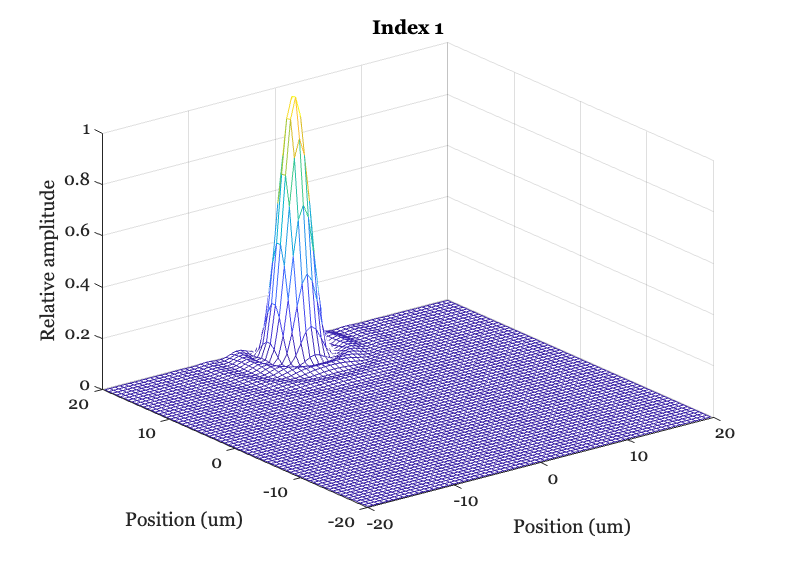

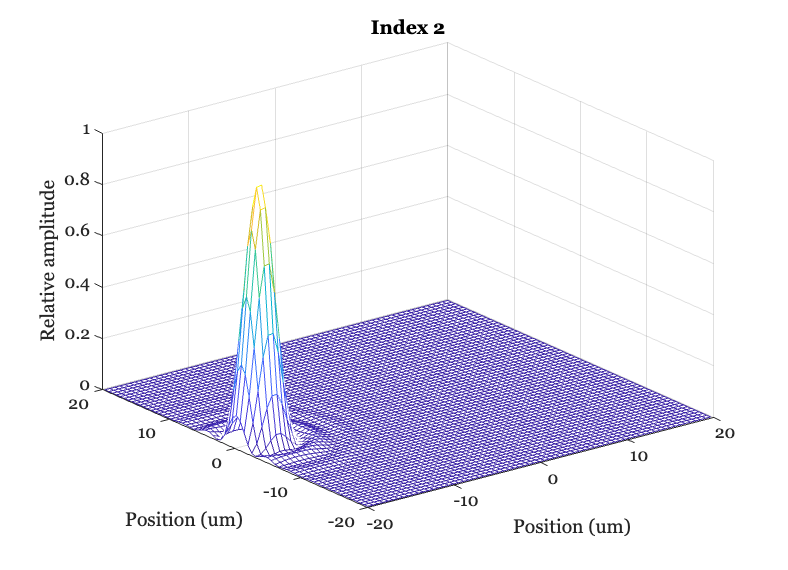

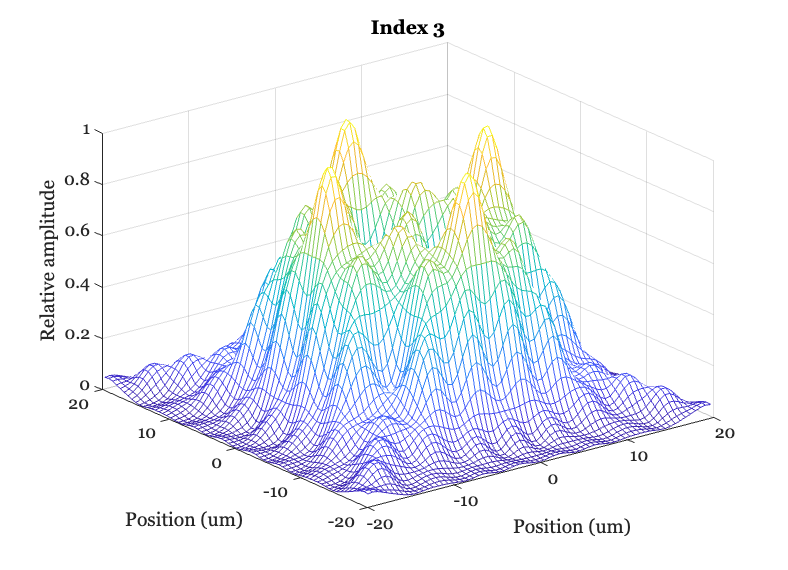

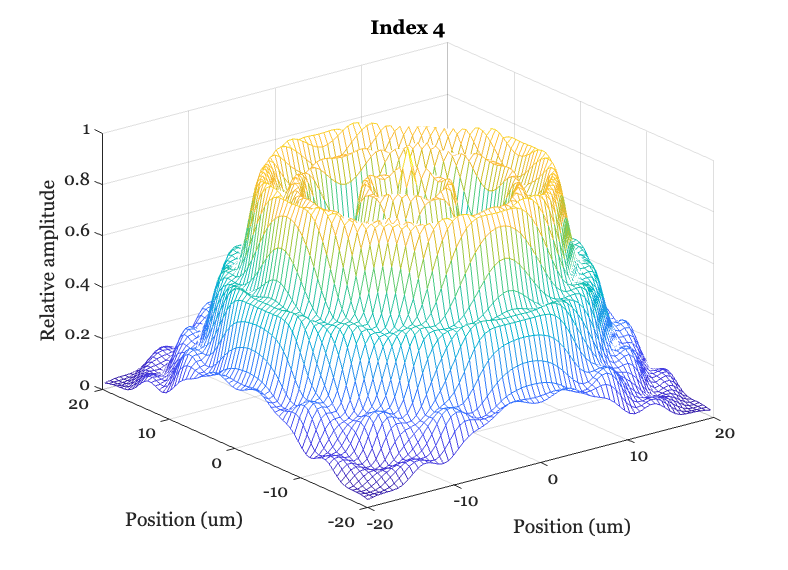

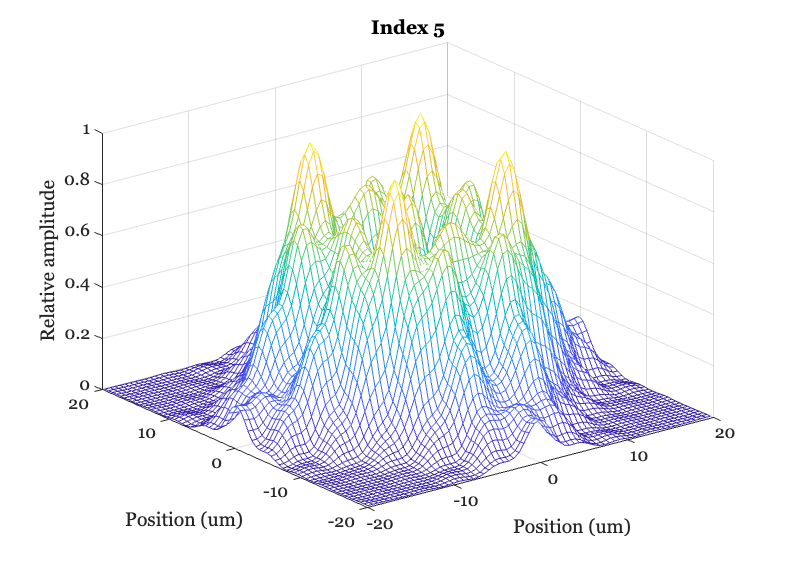

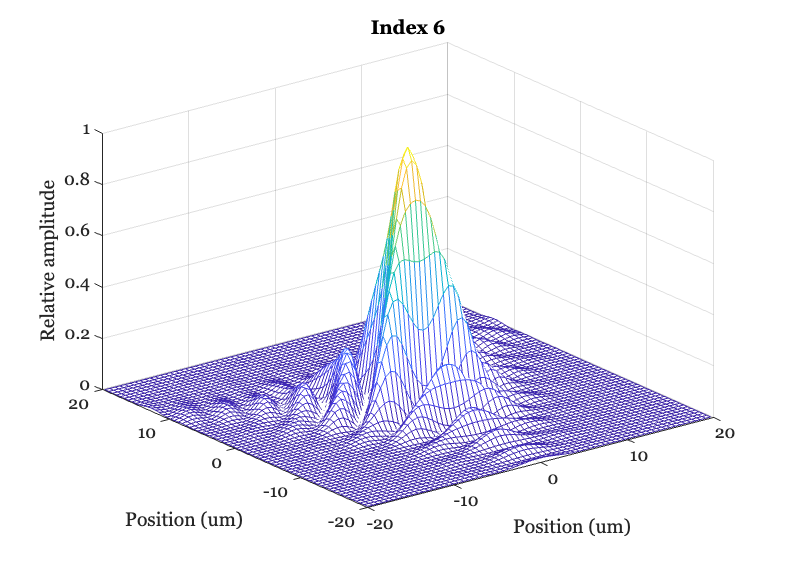

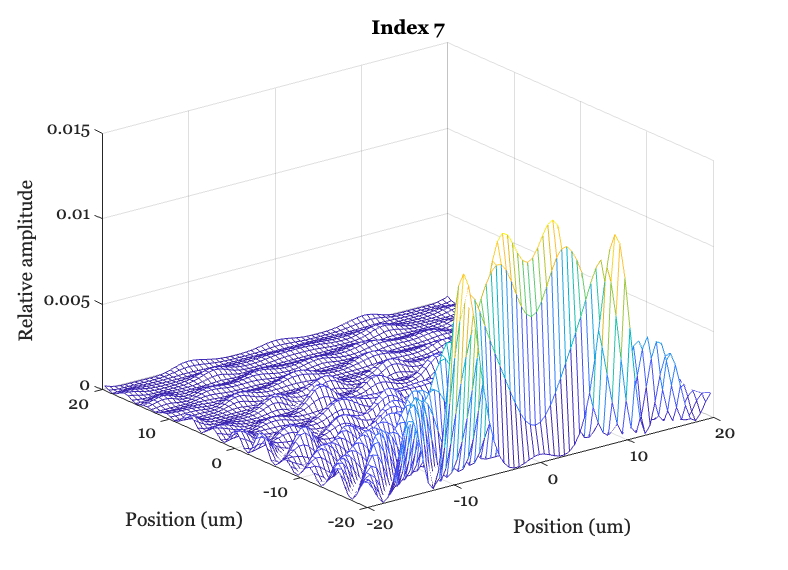

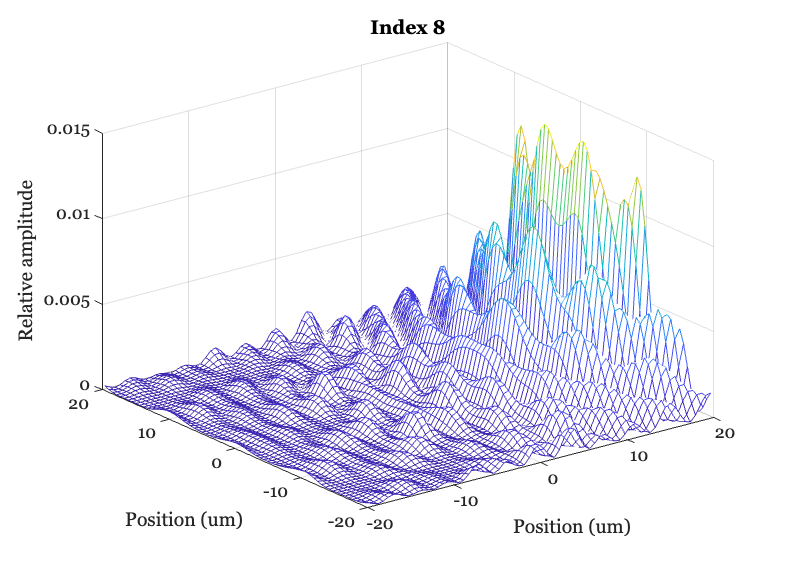

wvf0 = wvfCreate;
jindices = 1:9;
maxUM = 20; 
for ii = jindices
    ieNewGraphWin;
    insertCoeff = 2;
    wvf = wvfSet(wvf0,'zcoeffs',insertCoeff,ii);
    wvf = wvfCompute(wvf);
    [n,m] = wvfOSAIndexToZernikeNM(ii);
    wvfPlot(wvf,'psf normalized','unit','um','wave',wList,'plot range',maxUM,'window',false);
    title(sprintf('Index %d',ii))
end

## Longitudinal chromatic aberration (LCA)

Optical systems can have chromatic aberration, where one wavelength is brought into focus but others may be blurry because they are refracted closer or farther from the imaging plane. In this case, the PSF is dependent on wavelength.

The human eye has veru strong lateral chromatic aberration.  The wavefront code lets us set a variable to incorporate the human LCA as part of the calculation. In the human, this changes mainly Defocus. Aberrations other than "Defocus" are known to vary only slightly with wavelength. 

wvf0 = wvfCreate('wave',400:50:700);
wvf0 = wvfSet(wvf0,'lca method','human');

The human LCA itself is computed using a fairly standard function for the human eye.  As you can see from the plot below, the effect of human LCA is quite large.  It is possible to set other LCA functions, say for glass lenses.  We will illustrate that in another script.

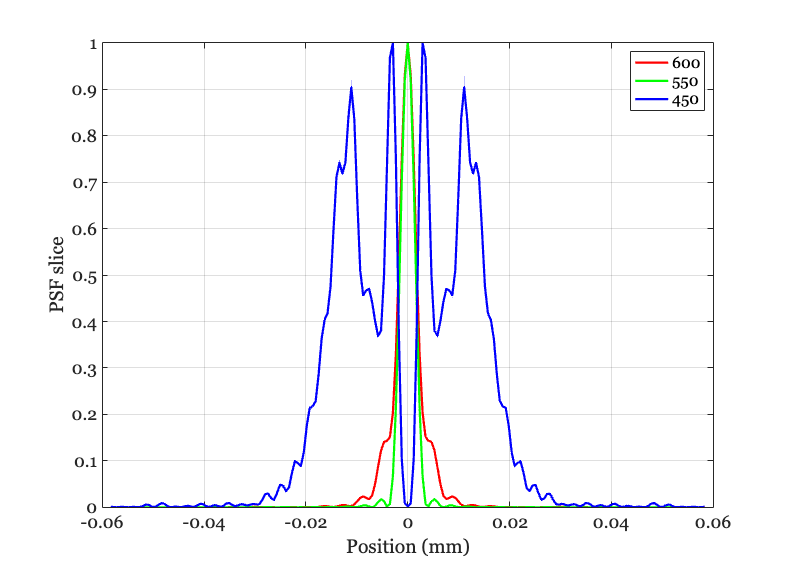

wvf0 = wvfCompute(wvf0);
ieNewGraphWin;
maxMM = 3; 
wvfPlot(wvf0,'1d psf normalized','unit','mm','wave',600,'plot range',maxMM/10,'window',false);
hold on; wvfPlot(wvf0,'1d psf normalized','unit','mm','wave',550,'plot range',maxMM/10,'window',false);
hold on; wvfPlot(wvf0,'1d psf normalized','unit','mm','wave',450,'plot range',maxMM/10,'window',false);
legend({'600','550','450'});